# Hydrogen Atom

## Radial Equation for Coulomb Potential

The hydrogen atom consists of a heavy, that we will assume below to be infinitely heavy in Born-Oppenheimer approximation, hence motionless proton of charge $e$ and electron of mass $m_{e}$ and charge $-e$ that is bound to the proton by Coulomb's attraction. The Coulomb attraction potential depends on distance $r$ between electron and proton (in SI units) as  


$$\begin{array}{cc}V(r)=-\frac{e^{2}}{4 \pi \epsilon_{0}} \frac{1}{r},& \qquad (1)\\ \end{array}$$


where $\epsilon_0$ is electric permittivity and $e$ is proton's charge. 

The radial equation for the hydrogen atom is (see Eq. (21) in live script *Spherically Symmetric Potential*)


$$\begin{array}{cc}-\frac{\hbar^{2}}{2 m_{e}} \frac{d^{2} u}{d r^{2}}+\left[-\frac{e^{2}}{4 \pi \epsilon_{0}} \frac{1}{r}+\frac{\hbar^{2}}{2 m_{e}} \frac{\ell(\ell+1)}{r^{2}}\right] u=E u .& \qquad (2)\\ \end{array}$$
 

Above $u(r) = rR(r)$, with a complete coordinate wave function $\psi(r, \theta, \phi)=R(r) Y(\theta, \phi)$, and $\ell\ge 0$ is a non-negative integer - the angular momentum quantum number. Angular momentum is a conserved (vector) quantity in problems with centrally symmetric potential.

Solutions of Eq. (2), eigen values $E$ and corresponding eigen functions $u(r)$, depend on quantum number $\ell$. For different values of $\ell=0,1,2,...$ electron feels  different effective potentials, sum of two terms in square brackets in left-hand-side of Eq. (2). Snippet below plots radial dependence of effective potential for $\ell=0,1,2,3$. 

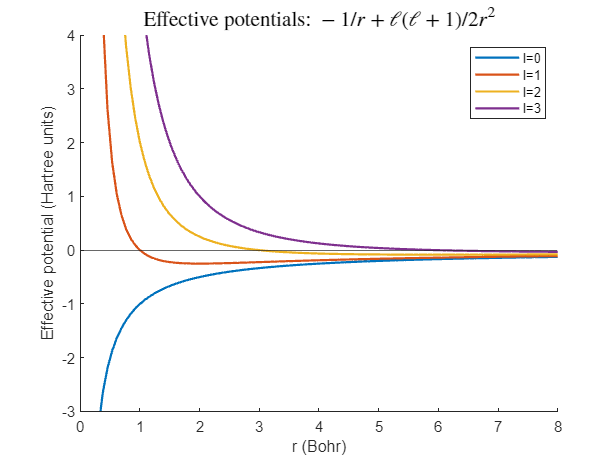

r = linspace(0.3, 8, 100)';  % radial grid 
figure
xlabel("r (Bohr)")
ylabel("Effective potential (Hartree units)")
title("Effective potentials: $-{1}/{r}+{\ell(\ell+1)}/{2r^{2}}$",interpreter='Latex', fontsize=14)
ylim([-3,4])
Legend=cell(4,1);
for l=0:3 
    line(r, -1./r+l*(l+1)./(2*r.^2));
    Legend{l+1}=strcat('l=', num2str(l));   
end
legend(Legend);
yline(0, handleVisibility='off') % suppressing legend of horizontal y=0 line

In general, for a given $\ell$ and depending on $V(r )$, Eq. (2)  can have infinite number of physically acceptable normalizable (hence describing negative energy bound-states) solutions for $u(r)$ (eigen functions) and $E$ (eigen values) which we can enumerate by a positive integer $n_{\ell}=1,2,...$

$(u_{1,\ell }(r),E_{1,\ell})$, $(u_{2,\ell}(r), E_{2, \ell })$,..., where $E_{1, \ell} \le E_{2, \ell}\le ...$  

For the Coulomb potential Eq. (1), as we will see below, 

$E_{n_{\ell},\ell}=-0.5E_h/ (n_{\ell}+l)^2$, 

as indicated in Fig.1, where $E_h$ is Hartree energy. Hence energy levels of hydrogen atom depend on the sum $n_{\ell}+\ell$.

The absolute lowest energy solution of hydrogen atom (ground state energy) is realized for $\ell=0$ case (called $1s$ state), since the effective potential that electron feels is most attractive for $\ell=0$. The ground state energy of hydrogen atom is $E_{1,0}=E_{1s}=-0.5E_h$, and this energy level is non-degenerate, not considering spin degeneracy (spin degeneracy of hydrogen atom's ground state is lifted by hyperfine coupling between electron's and proton's spins, see Ref.  [1]). 

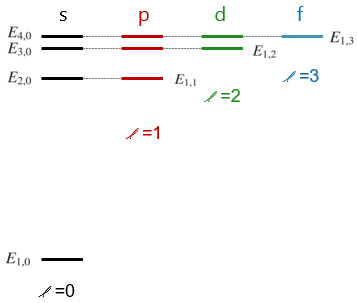

Figure1: Sketch of hydrogen's energy levels $E_{n_{\ell},\ell}$ in different $\ell$ sectors.

The positive integer $n_0$, enumerating $s$-states' energy levels$1s$, $2s$, $3s$,... will be denoted in the following by $n$ and it is called **the principle quantum number**. All different energy eigen values (energy levels) of hydrogen atom can be labeled by principle quantum number alone and these energy levels are $n$-times degenerate with $\ell$: For any positive integer $n$ there exist same energy solutions as $E_{ns}$ for the following values of $\ell =0,1,...,n-1$. The degeneracy of energy levels with $\ell$ is due to high symmetry of the Coulomb potential in 3D, see Ref. [2]. The degeneracy with respect to a magnetic quantum number $m=-\ell, -\ell+1,...\ell$ (which does not appear in Eq. (2)) is, on the other hand, entirely due to spherical symmetry of $V(r)$ that led to separation of variables $\psi(r, \theta, \phi)=R(r) Y(\theta, \phi)$ and eventually to energy eigen value equation Eq. (2). 

### Numerical Solution of Radial Equation 

In code snippet below we obtain numerically eigen values $E$ of radial equation Eq. (2) for different sectors of $\ell$, adopting [Hartree atomic units](https://en.wikipedia.org/wiki/Hartree_atomic_units). In atomic units Eq. (2) looks: $-\frac{1}{2 } \frac{d^{2} u}{d r^{2}}-\left[\frac{1}{r}-\frac{\ell(\ell+1)}{2r^{2}}\right] u=E u$. We define a finite radial grid and approximate second derivative using central finite difference approximation. We show that up to negligible error caused by finite-size, discrete approximation and especially by numerically challenging $r=0$ point for $\ell=0$ sector, energy levels are numerically $E_{n_{\ell},\ell}=-0.5/ (n_{\ell}+l)^2$.

l=1;     % select angular momentum quantum number
Rmax = 50*(l+1);                % maximal radial extent of simulation box in units of Bohr radius
Nr = 500;                       % number of radial points      
Rmin=0.1;                       % avoid r=0 point, especially for l=0 sector. For l>0 decrease Rmin to 0.00001 to see that results are stable     
r = linspace(Rmin, Rmax, Nr)';  % radial grid 
dr=Rmax/Nr;                     % radial step
d  = ones(Nr,1);                
Lap_r  = spdiags([d -2*d d],[-1 0 1],Nr,Nr)/dr^2;        % second derivative as Nr x Nr sparse matrix with -2/dr^2 on main (0) diagonal and 1/dr^2 on lower (-1) and upper (1) diagonals  
H =-0.5*Lap_r - spdiags(1./r-l*(l+1)./(2*r.^2),0,Nr,Nr); % sparse Hamiltonian matrix
[V,E]=eigs(H,4,'smallestreal'); % 4 lowest eigen values in each angular momentum sector      
diag(E)

ans =    -0.1250
   -0.0555
   -0.0312
   -0.0200


### Solving Radial Equation Analytically

To solve Eq. (2) we introduce denotion: 


$$\begin{array}{cc}\kappa \equiv \frac{\sqrt{-2 m_{e} E}}{\hbar}.& \qquad (3)\\ \end{array}$$
 

To check dimension of $\kappa$, we can create` symunit `variable `v` and use `simplify` function

v = symunit;
simplify(sqrt(v.m_e*v.J)/v.h_bar)

$$ans = 2880835525982829992.0059955739757\,\pi \,\frac{1}{m}$$

We see that dimension of $\kappa$ is inverse length. We can confirm this result by using the `checkUnits `function

checkUnits(sqrt(v.m_e*v.J)/v.h_bar==1/v.m,'Compatible')

ans = logical
   1


For bound states, $E$ is negative, so $\kappa$ is real. Dividing both sides of Eq. (2) by $E$ gives


$$\begin{array}{cc}\frac{1}{\kappa^{2}} \frac{d^{2} u}{d r^{2}}=\left[1-\frac{m_{e} e^{2}}{2 \pi \epsilon_{0} \hbar^{2} \kappa} \frac{1}{(\kappa r)}+\frac{\ell(\ell+1)}{(\kappa r)^{2}}\right] u .& \qquad (4)\\ \end{array}$$
 

This suggests that we introduce dimensionless parameters


$$\begin{array}{cc}\rho \equiv \kappa r, \quad \text { and } \quad \rho_{0} \equiv \frac{m_{e} e^{2}}{2 \pi \epsilon_{0} \hbar^{2} \kappa}.& \qquad (5)\\ \end{array}$$


We can check that $\rho_0$ is dimensionless, hence expression in numerator in Eq. (5) has same dimension as denominator

simplify(v.m_e*v.e^2*v.m/(v.h_bar^2*v.e_0))

$$ans = 24060740305.786304858708767922221\,\pi^{2}$$

checkUnits(v.m_e*v.e^2*v.m==v.h_bar^2*v.e_0,'Compatible')

ans = logical
   1


In dimensionless variables radial equation becomes:


$$\begin{array}{cc}\frac{d^{2} u}{d \rho^{2}}=\left[1-\frac{\rho_{0}}{\rho}+\frac{\ell(\ell+1)}{\rho^{2}}\right] u .& \qquad (6)\\ \end{array}$$
 

Physically acceptable (resulting in well-behaved wave function both at origin and at infinity) solution of Eq. (6), describing the bound state of electron (negative energy normalizable states) is only possible for $\rho_0=2n$ (hence $\kappa=1/(n a_0)$) with positive integer $n$ such that $n>l$ (details of mathematical proof of quantization of $\rho_0$ can be seen in many textbooks of quantum mechanics). 

We use symbolic toolbox to solve Eq. (6) 

syms u(rho) rho0 l a0 r
assume(rho,{'positive','real'})
assume(rho0/2,{'positive','integer'})
assume(a0,{'positive','real'})

ode = laplacian(u,rho)==(1-rho0/rho+l*(l+1)/rho^2)*u

$$ode(rho) = \frac{\partial^{2}}{\partial \rho^{2}}u\left(\rho \right)=u\left(\rho \right)\,\left(\frac{l\,\left(l+1\right)}{\rho^{2}}-\frac{\rho_{0}}{\rho }+1\right)$$

dsolve(ode)

$$ans = C_{1}\,M_{\frac{\rho_{0}}{2},l+\frac{1}{2}}(2\,\rho )+C_{2}\,W_{\frac{\rho_{0}}{2},l+\frac{1}{2}}(2\,\rho )$$

In general Whittaker M and W functions are linearly independent functions, but for the physically acceptable solutions ($\rho_0=2n$ and $n>\ell\ge0$, with both $n$ and $\ell$ integers) they coincide up to a constant factor. We show this below by plotting two functions together.   

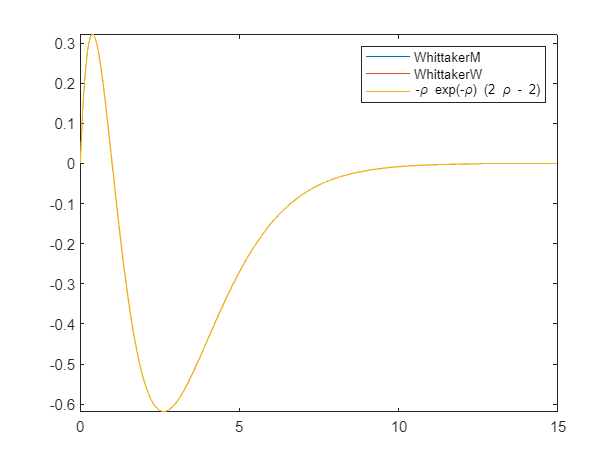

% plot of 2 solutions
u1 = whittakerM(rho0/2, l + 1/2, 2*rho);
u2 = whittakerW(rho0/2, l + 1/2, 2*rho);
u3=exp(-rho)*rho^(l+1)*laguerreL(rho0/2-l-1,2*l+1,2*rho); % yet another representation of the Radial equation solution 
                                                          % in terms of the generalized Laguerre polinomials Eq.(15)
rho00=4;
l_allowed = string((0:rho00/2-1));
l0=double(l_allowed(1));  % note l must be less than rho0/2
% alpha is constant factor between two Whittaker functions
alpha=whittakerM(rho00/2, l0 + 1/2, 1)/whittakerW(rho00/2, l0 + 1/2, 1);
% beta is a constant factor between Whittaker W and u3
beta=whittakerW(rho00/2, l0 + 1/2, 1)/ (exp(-1/2)*(1/2)^(l0+1)*laguerreL(rho00/2-l0-1,2*l0+1,1));
figure
fplot(subs(u1,{rho0,l},{rho00,l0})/(alpha*beta),[0,15])
hold on
fplot(subs(u2,{rho0,l},{rho00,l0})/beta,[0,15])
legend({'WhittakerM','WhittakerW'})
hold on
fplot(subs(u3,{rho0,l},{rho00,l0}),[0,15]);

To make a closer contact to quantum mechanics textbooks we contrast Eq. (6) with a solution of an associated Laguerre function $y_j^k$, with $j=0,1,2,...$ and $k=1,2,3,...$ satisfying the following second order differential equation:


$$\begin{array}{cc} \frac{d^2 y_j^{k^}(x)}{d x^2}=\left(1-\frac{2 j+k+1}{x}+\frac{k^2-1}{4 x^2}\right) y_j^k(x).& \qquad (7)\\ \end{array}$$


Solution to Eq. (7) is


$$\begin{array}{cc}y_j^k(x)=e^{-x} x^{(k+1) / 2} L_j^k(2x),& \qquad (8)\\ \end{array}$$
 

where 


$$\begin{array}{cc}L_q^p(x) \equiv(-1)^p\left(\frac{d}{d x}\right)^p L_{p+q}(x)& \qquad (9)\\ \end{array}$$
 

is **associated Laguerre polynomial**, and


$$\begin{array}{cc}L_q(x) \equiv \frac{e^x}{q !}\left(\frac{d}{d x}\right)^q\left(e^{-x} x^q\right)& \qquad (10)\\ \end{array}$$
 

is the $q$-th **Laguerre polynomial**. Thus, to map Eq. (6) to Eq. (7)  we have to make the following identifications: 


$$\begin{array}{cc}\rho_0 = 2j+k+1& \qquad (11)\\ \end{array}$$
 

and 


$$\begin{array}{cc}\ell(\ell+1) = \frac{k^2-1}{4}.& \qquad (12)\\ \end{array}$$


From Eq. (12) we get that 


$$\begin{array}{cc}k = 2\ell+1& \qquad (13)\\ \end{array}$$
 

so that,


$$\begin{array}{cc}\rho_0=2(j+\ell+1)\equiv 2n,& \qquad (14)\\ \end{array}$$
 

where $n$ is **principal quantum number**. We have a solution of $u$ as 


$$\begin{array}{cc}u(\rho) = u_{n\ell}(\rho)=e^{-\rho} \rho^{\ell+1} L_{n-\ell-1}^{2\ell+1}(2\rho)& \qquad (15)\\ \end{array}$$


 and 


$$\begin{array}{cc}R_{n \ell}(r)=\frac{u_{n \ell}(r)}{r}=\frac{1}{r} (\kappa r)^{\ell+1} e^{-\kappa r}  L_{n-\ell-1}^{2\ell+1}(2\kappa r).& \qquad (16)\\ \end{array}$$


So far we did not care about normalizing radial wave function. If we impose normalization 


$$\displaystyle\int_0^{\infty} R_{n\ell}^2 r^2 dr=1, \qquad (16a)$$


then normalized solution is $R_{n \ell}(r)=\frac{const}{r} (\kappa r)^{\ell+1} e^{-\kappa r}  L_{n-\ell-1}^{2\ell+1}(2\kappa r)$, with $\kappa=1/(n a_0)$ and $const=\frac{2^{\ell+1}} {\sqrt{a_0 n}} \sqrt{\frac{(n-\ell-1)!}{n(n+\ell)!}}$. Importantly, apart from the numerical factors, the normalization constant carries an additional dimension of inverse length to the power of one-half, $\frac{1}{\sqrt{a_0}}$.

Properly normalized $R_{n\ell}$ can be read in Eq. (25) below.

n = 3;
% we can take any of the 3 equivalent functions u1, u2, or u3
u = subs(u2,rho,(r/(a0*n)));
R = u/r; 
figure
subplot(1,2,1)
hold on
curve1=zeros(1,n+1);
curve1(1) = yline(0,'LineStyle','--');
subplot(1,2,2)
hold on
curve2=zeros(1,n+1);
curve2(1) = yline(0,'LineStyle','--');
r0_list = [];
for ll=0:n-1
    Rnl = subs(R,{rho0,l},{2*n,ll});
    % normalization of R(r)
    integral_R = int(Rnl^2*r^2,r,[0,inf]);
    Rnl = Rnl/sqrt(integral_R);
    % check if need scale by -1
    ipos = double(subs(Rnl,[a0,r],[1,1e-2]) > 0);
    Rnl = Rnl * (-1)^(ipos-1);
    % print and plot R(r)
    fprintf('R%d%d = ', n,ll);
    displayFormula("Rnl")
    subplot(1,2,1)
    curve1(ll+2) = fplot(subs(Rnl,a0,1),'DisplayName',['$l$=',num2str(ll)]);
    subplot(1,2,2)
    curve2(ll+2) = fplot(subs(Rnl^2*r^2,a0,1),'DisplayName',['$l$=',num2str(ll)]);
    int(subs(Rnl^2*r^2,a0,1),r,0,inf);
    P = subs(Rnl^2*r^2,a0,1);
    r0 = solve(diff(P,r) == 0, r);
    g0 = double(subs(P,r,r0)) > 0;
    r0 = round(double(r0(g0)),3);
    P = subs(P,r,r0);
    for i=1:length(r0)
        line([r0(i) r0(i)],[0,P(i)],'Color',[.7 .7 .7],'LineStyle','--')
    end
    r0_list = [r0_list; r0];
end

R30 = 

$$\frac{\sqrt{3}\,{\mathrm{e}}^{-\frac{r}{3\,a_{0}}}\,\left(\frac{4\,r^{2}}{9\,{a_{0}}^{2}}-\frac{4\,r}{a_{0}}+6\right)}{27\,{a_{0}}^{3/2}}$$

R31 = 

$$-\frac{\sqrt{6}\,r\,{\mathrm{e}}^{-\frac{r}{3\,a_{0}}}\,\left(\frac{2\,r}{3\,a_{0}}-4\right)}{81\,{a_{0}}^{5/2}}$$

R32 = 

$$\frac{2\,\sqrt{30}\,r^{2}\,{\mathrm{e}}^{-\frac{r}{3\,a_{0}}}}{1215\,{a_{0}}^{7/2}}$$

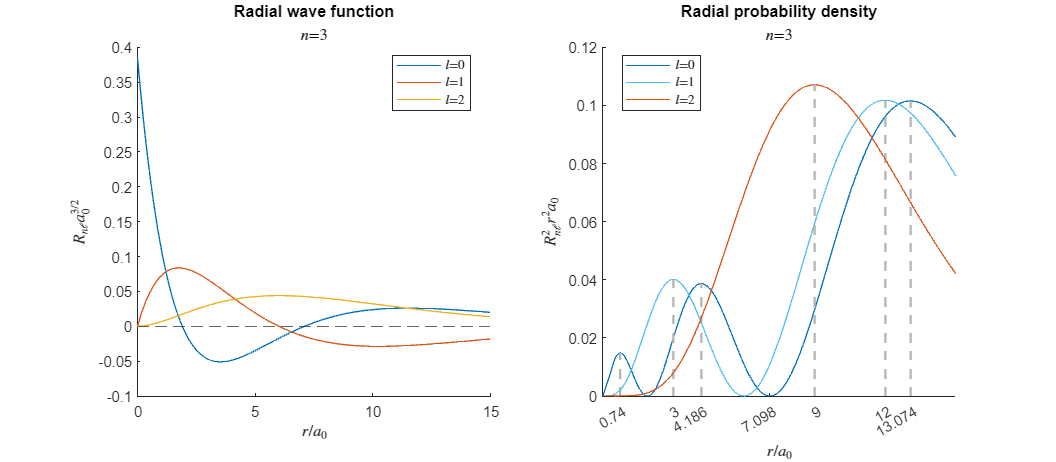

subplot(1,2,1)
legend(curve1(2:end),'Location','best', Interpreter='latex')
xlim([0 15])
xticks([0 5 10 15])
xlabel('$r/a_0$',Interpreter='latex')
ylabel('$R_{n\ell}a_0^{3/2}$',Interpreter='latex')
title("Radial wave function")
subtitle(['$n$=', num2str(n)],Interpreter='latex')
hold off
subplot(1,2,2)
legend(curve2(2:end),'Location','best',Interpreter='latex')
xlim([0 15])
xticks(sort(r0_list))
xlabel('$r/a_0$',Interpreter='latex')
ylabel('$R_{n\ell}^2r^2a_0$',Interpreter='latex')
title("Radial probability density")
subtitle(['$n$=', num2str(n)],Interpreter='latex')
hold off
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 0 400 0])

In the above plots, we multiplied normalized radial wave function and radial probability density with appropriate powers of Bohr radius to make $y$ axis in both cases dimensionless, similar to $x$-axis that measures the distance in units of Bohr radius, hence is dimensionless.

Plotting the radial wave function with different values of $\ell$, we see that except for $s$-orbital states (with $\ell=0$), all other states with $\ell>0$  ($p, d, f$,...) have nodes (vanish) at the position of the nucleus $r=0$. This is the reason why contact Fermi interaction in hyperfine coupling is relevant for $s$-orbital electrons [1]. 

## Ground State Energy

By definition of $\rho_0$ in Eq. (5), it determines energy of the bound state $E$ as: 


$$\begin{array}{cc}E=-\frac{\hbar^{2} \kappa^{2}}{2 m_e}=-\frac{m_{e} e^{4}}{8 \pi^{2} \epsilon_{0}^{2} \hbar^{2} \rho_{0}^{2}}.& \qquad (17)\\ \end{array}$$
 

So the allowed negative eigen energies (corresponding to bound states) of hydrogen atom due to Eq. (14) are


$$\begin{array}{cc}E_{n}=-\left[\frac{m_{e}}{2 \hbar^{2}}\left(\frac{e^{2}}{4 \pi \epsilon_{0}}\right)^{2}\right] \frac{1}{n^{2}}=\frac{E_{1}}{n^{2}}, \quad n=1,2,3, \ldots& \qquad (18)\\ \end{array}$$
 

This is the famous Bohr formula - one of the most important achievements of quantum mechanics. Combining Eqs. (17) and (18), we find that


$$\begin{array}{cc}\kappa=\left(\frac{m_{e} e^{2}}{4 \pi \epsilon_{0} \hbar^{2}}\right) \frac{1}{n}=\frac{1}{a_0 n},& \qquad (19)\\ \end{array}$$
 

where


$$\begin{array}{cc}a_0 \equiv \frac{4 \pi \epsilon_{0} \hbar^{2}}{m_{e} e^{2}}=0.529 \times 10^{-10} \mathrm{ m}& \qquad (20)\\ \end{array}$$
 

is the Bohr radius. It follows that


$$\rho=\frac{r}{a_0 n}. \qquad (21)$$


The ground state (that is, the state of the lowest energy) corresponds to the case $n=1$; putting in the accepted values for the physical constants, we get:


$$\begin{array}{cc}E_{1}=-\left[\frac{m_{e}}{2 \hbar^{2}}\left(\frac{e_e\cdot e_n}{4 \pi \epsilon_{0}}\right)^{2}\right]=-0.5 E_h\simeq-13.6 eV.& \qquad (22)\\ \end{array}$$


In other words, the absolute value of binding energy of hydrogen atom in ground state (the amount of energy you have to impart to the electron to ionize the atom that is in ground state) is half a Hartree $0.5E_h\simeq 13.6 eV$.

This is a hugely important number in physics, not only for micro world, but also for astronomy and cosmology (dealing with the largest scale phenomena). In particular, this value determines the temperature of cosmic microwave background radiation at the time of recombination, and hence also the age of the universe.  

In Eq. (22) we deliberately represented $e^2=-e_ee_n$ as a product of electron charge $e_e=-e$ and charge of the nucleus $e_n=Ze$ (with $Z=1$ for hydrogen atom), to show that hydrogen energy levels depend on the square of the nuclear charge. This will help us compare hydrogen atom ground state energy with helium's ($Z=2$) ground state energy estimated within the independent electron approximation scheme: when increasing nuclear charge by factor of $Z$, the contribution to the ground state energy from a **single electron** given in Eq. (22) should be multiplied by $Z^2$. In the following live scripts we will denote ground state energy usually by index $0$ like $E_0$.

## Spatial 3D Wave Function

The spatial wave functions are labeled by **principal quantum number**, **azimuthal quantum number**, and **magnetic quantum number** $(n, \ell, m)$ :


$$\psi_{n \ell m}(r, \theta, \phi)=R_{n \ell}(r) Y_{\ell}^{m}(\theta, \phi). \qquad (23)$$


Applying the normalization condition


$$\begin{array}{cc}\int \psi_{n \ell m}^{*} \psi_{n^{\prime} \ell^{\prime} m^{\prime}} r^{2} d r d \Omega=\delta_{n n^{\prime}} \delta_{\ell \ell^{\prime}} \delta_{m m^{\prime}}& \qquad (24)\\ \end{array}$$
 

the final expression of wave function for hydrogen atom is


$$\begin{array}{cc}\psi_{n \ell m}(r,\theta,\phi)=\sqrt{\left(\frac{2}{n a_0}\right)^{3} \frac{(n-\ell-1) !}{2 n(n+\ell) !}} e^{-r / n a_0}\left(\frac{2 r}{n a_0}\right)^{\ell}\,L_{n-\ell-1}^{2 \ell+1}\left(\frac{2 r }{ n a_0}\right)\,Y_{\ell}^{m}(\theta, \phi).& \qquad (25)\\ \end{array}$$


We will check below that the wave function in Eq. (25) obeys normalization in Eq. (24) numerically for any trial combination of positive integer $n>0$ and nonnegative integer $\ell<n$, (we remind that $\int Y_{\ell}^{m \, *}(\theta, \phi)Y_{\ell'}^{m'}(\theta, \phi) d\Omega=\delta_{m,m'}\delta_{\ell,\ell'}$).

% Snippet defines symbolically R_nl, checks that R_nl^2*r^2 integrates to 1 for r from 0 to infinity Eq. (16a) and 
% confirms orthogonality of radial wave functions for the same value of l but different values of n.
syms  r n l a_0 positive
R_nl=sqrt((2/(n*a_0))^3*factorial(n-l-1)/(2*n*factorial(n+l)))*exp(-r/(a_0*n))*((2/(n*a_0)*r)^(l))*laguerreL(n-l-1,2*l+1,2/(n*a_0)*r)

$$R\_nl = \frac{2\,{\mathrm{e}}^{-\frac{r}{a_{0}\,n}}\,\sqrt{\left(n-l-1\right)!}\,\mathrm{laguerreL}\left(n-l-1,2\,l+1,\frac{2\,r}{a_{0}\,n}\right)\,{\left(\frac{2\,r}{a_{0}\,n}\right)}^{l}}{{a_{0}}^{3/2}\,n^{2}\,\sqrt{\left(l+n\right)!}}$$

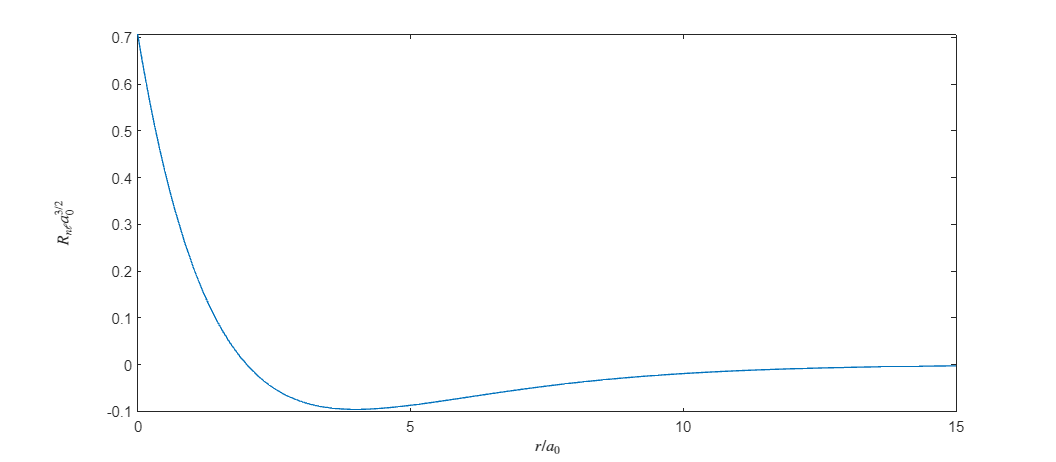

figure
fplot(subs(a_0^(3/2)*R_nl,{n,l,a_0},{2,0,1}))
xlim([0 15])
xlabel('$r/a_0$','interpreter','latex')
ylabel('$R_{n\ell}a^{3/2}_0$', Interpreter='latex') 

double(int(subs(R_nl,{n,l},{3,0})*subs(R_nl,{n,l},{3,0})*r^2,r,[0,inf])) %check normalization of R_nl as in Eq. (16a) 

ans = 1

double(int(subs(R_nl,{n,l},{2,0})*subs(R_nl,{n,l},{3,0})*r^2,r,[0,inf])) %check orthogonality of R_nl and R_n'l' for l=l' and n different from n'

ans = 0

For arbitrary $n\ge 1$, the possible values of $\ell$ are


$$\begin{array}{cc}\ell=0,1,2, \ldots, n-1.& \qquad (26)\\ \end{array}$$
 

and the possible values of $m$ are 


$$\begin{array}{cc}m = -\ell, -\ell+1, \ldots, \ell-1, \ell.& \qquad (27)\\ \end{array}$$
 

Snippet below will plot modulus square of the wave function for different values of $n \ge 1$ and $\ell$ and $m$ satisfying Eqs. (26) and (27) respectively.

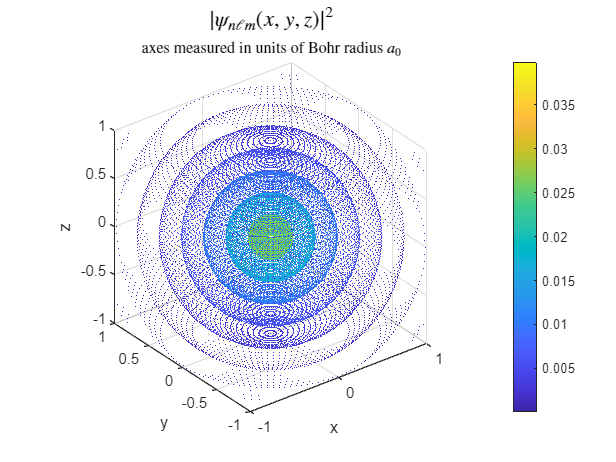

syms rho0 l r rho a0 positive real
u2 = whittakerW(rho0/2, l + 1/2, 2*rho);

n0=  2;     % select principal quantum number
l_allowed = string((0:n0-1));
ll = double(l_allowed(1)); % select azymuthal quantum number
m_allowed = string((-ll:ll));
m = double(m_allowed(1));  % select magnetic quantum number
u = subs(u2,rho,(r/(a0*n0)));
R = u/r; 
Rnl = subs(R,{rho0,l},{2*n0,ll});
% normalization of R(r)
integral_R = int(Rnl^2*r^2,r,[0,inf]);
Rnl = Rnl/sqrt(integral_R);

syms theta phi x real
assumeAlso(phi>=0 & phi <= 2*pi)
assumeAlso(theta>=0 & theta <= pi)
pl = legendreP(ll,x);
plm = (-1)^abs(m)*sin(theta)^abs(m)*subs(diff(pl,x,abs(m)),x,cos(theta));
a = (2*ll+1)*factorial(ll-abs(m));
b = 4*sym(pi)*factorial(ll+abs(m));
C = sqrt(a/b);
ylm = C .*plm .*exp(1i*abs(m)*phi);
if m < 0
    ylm = (-1)^abs(m)*conj(ylm);
end

dx = pi/60;
col = 0:dx:pi;
az = 0:dx:2*pi;
radi = 0:0.2:10;
[Phi,Theta,Radi] = meshgrid(az,col,radi);

Plm = legendre(ll,cos(Theta));
if ll ~= 0
    Plm = reshape(Plm(abs(m)+1,:,:),size(Phi));
end
Ylm = double(C) .*Plm .*exp(1i*abs(m)*Phi);
if m < 0
    Ylm = (-1)^abs(m) * conj(Ylm);
end
F_Rnl = matlabFunction(subs(Rnl,{a0},{1}));
Rnl_value = F_Rnl(Radi);
Psi = Rnl_value .* Ylm;
Rho = abs(Psi).^2;
intens_control=10^(-4-ll);
pos = Rho>intens_control;   % adjust the lower bound to play with the plot intensities
Rho = Rho(pos);
Phi = Phi(pos);
Theta = Theta(pos);
Radi = Radi(pos);
[X,Y,Z] = sph2cart(Phi,pi/2-Theta,Radi);
figure
scatter3(X(:),Y(:),Z(:),1e-1,Rho(:))
xlim([-(3*ll+1) 3*ll+1])
ylim([-(3*ll+1) 3*ll+1])
zlim([-(3*ll+1) 3*ll+1])
pbaspect([1 1 1])
xlabel('x') 
ylabel('y') 
zlabel('z')
colorbar
title("$|\psi_{n\ell m}(x,y,z)|^2$", Interpreter='latex',Fontsize=15)
subtitle("axes measured in units of Bohr radius $a_0$", Interpreter='latex')

## Shell Model of an Atom

The shell model of an atom is a model in quantum mechanics that explains the structure of electrons in an atom based on their *energy levels* and *quantum numbers *and the fact that electrons are fermions, obeying the Pauli principle of exclusion. In this model, electrons occupy different shells, which are energy levels that are separated by a certain energy gap. The shells are labeled by the principal quantum number $n$, which describes the energy level of the electron. An atom's $n$ -th electron shell can accommodate $2n^2$ electrons, the factor of $2$ accounting for the spin degeneracy.

Each shell can be further divided into subshells that are labeled by the angular momentum quantum number $\ell$ and its magnetic quantum number $m$. Number $\ell$ ranges from 0 to $n-1$ and determines the shape of the orbital. The values $\ell = 0, 1, 2, 3$ correspond to the $s, p, d$, and $f$ orbitals, respectively. Only $s$-orbitals are spherically symmetric. The magnetic quantum number $m$ specifies the orientation of the orbital in space and varies from $-\ell$ to $+\ell$. Each subshell can hold up to $2(2\ell+1)$ electrons.

The shell model provides a simplified picture of the electronic structure of an atom and has applications in understanding electron configurations and predicting the chemical behavior of elements.

### Radial Electron Density in Shell Model

Below we will assume that we have $N$ electrons and each is located in different (lowest energy) $s$-orbitals ($1s, 2s,...Ns$) and plot radial electron density for such case (see Exercise 1 for including orbitals with $\ell>0$).   

syms r n positive
l=0;
a_0=1;
R=sqrt((2/(n*a_0))^3*factorial(n-l-1)/(2*n*factorial(n+l)))*exp(-r/(a_0*n))*((2/(n*a_0)*r)^(l))*laguerreL(n-l-1,2*l+1,2/(n*a_0)*r)

$$R = \frac{2\,\sqrt{\left(n-1\right)!}\,{\mathrm{e}}^{-\frac{r}{n}}\,\mathrm{laguerreL}\left(n-1,1,\frac{2\,r}{n}\right)}{n^{2}\,\sqrt{n!}}$$

figure;
N=2; % select number of electrons

rho= subs(R^2/(4*pi),n,1);           % contribution to electron density from 1s-orbital


for j=2:N
     rho=rho+subs(R^2/(4*pi),n,j);   % contributions to electron density from higher s-orbitals 2s, 3s,... are added one at a step
end

Next we check normalization of electron density: $\int \rho(\mathbf{r})d\mathbf{r}= 4\pi \int \rho(r) r^2 dr =N$.

int(4*pi*rho*r^2,r,0,inf) 

$$ans = 2$$

Finally we plot radial dependence of radial electron density $4\pi \rho(r)r^2$

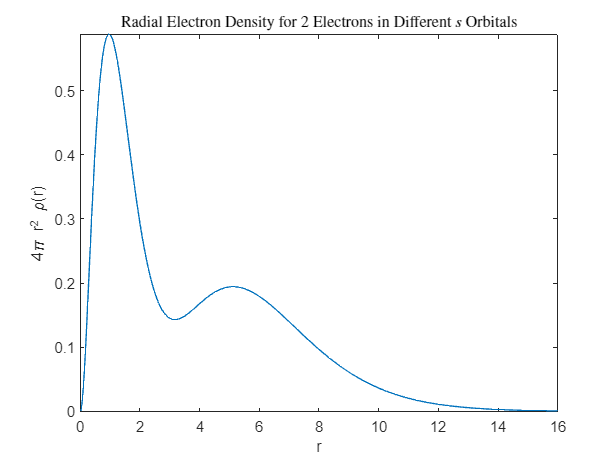

fplot(4*pi*rho*r^2);
xlim([0,8*N])
xlabel('r')
ylabel('4\pi r^2 \rho(r)')
title("Radial Electron Density for "+num2str(N) +" Electrons in Different $s$ Orbitals",Interpreter='latex')

Note, when $N$ electrons occupy different $s$-orbitals there are $N$ bumps (local maxima) in $4 \pi\rho( r) r^2$, whereas electron density $\rho(r )$ is a monotonically decreasing function with a maximum at $r=0$.

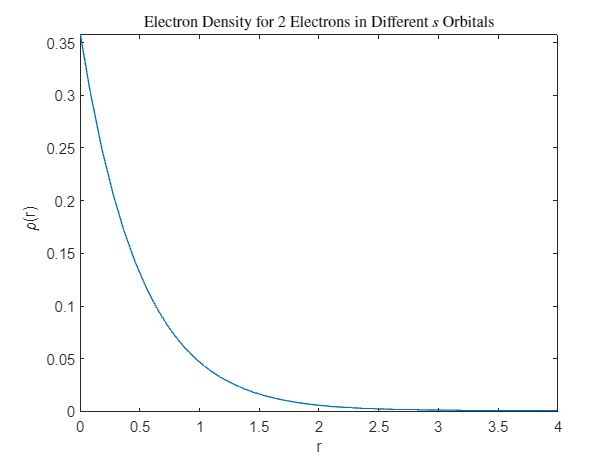

fplot(rho);
xlim([0,4])
xlabel('r')
ylabel(' \rho(r)')
title("Electron Density for "+num2str(N) +" Electrons in Different $s$ Orbitals",Interpreter='latex')

For $N=2$ in the ground state of helium atom (orthohelium spin-triple state) electron coordinate configuration is $1s 2s$ and is antisymmetric with respect to exchanging coordinates of two electrons. 

## ** Exercises**

**Exercise 1:** Take neon atom with 10 electrons. Assume electrons do not interact with each other. Assume that in the ground state $1s$, $2s$, and $2p$ orbitals (subshells) are completely filled by 2,  2, and 6 electrons respectively (with spin up and spin down electrons). Calculate and plot ground state electron density $\rho_0 (\mathbf{r} )=\rho_{0 \uparrow}(\mathbf{ r})+\rho_{0 \downarrow}(\mathbf{ r})$, where

 
$$\rho_{0\uparrow}(\mathbf{r}) =\rho_{0\downarrow}(\mathbf{ r})=\sum _{n,\ell,m}  |\psi_{n\ell m}(\mathbf{ r})|^2= |\psi_{100}(\mathbf{ r})|^2+ |\psi_{200}(\mathbf{r})|^2+ \sum_{m=(-1,0,1)}|\psi_{21m}(\mathbf{ r})|^2.$$


Hint: use $\displaystyle\sum^{\ell}_{m=-{\ell}} Y_{\ell}^{m *}(\theta ,\phi) Y_{\ell}^{m }(\theta ,\phi)=\frac{2\ell+1}{4\pi}$.

**Exercise 2:** Suppose electron in hydrogen atom is in superposition state $\psi=(\psi_{210}+\psi_{21-1} +\psi_{211})/\sqrt{3}$. Plot $| \psi(x,y,z)|^2$. Does it have spherical symmetry?    

## **References**

[1] T. Vekua, [Breit-Rabi diagram for alkali metal atoms](https://www.mathworks.com/matlabcentral/fileexchange/87819-breit-rabi-diagram-for-alkali-metal-atoms?s_tid=srchtitle).

[2] L. I. Schiff, *Quantum Mechanics,* 3rd Edition, McGraw-Hill, New York (1968).